clc;
clear;

Calculando o Tau e o Kcc

opts = detectImportOptions('dados_aquecedor_matlab.csv');
T = readtable('dados_aquecedor_matlab.csv', opts);
time = T.time;
temp_offset = T.temp_offset;

% Achando tau e o ganho Kcc
stable_temperature = 26.0;
aux_temp = stable_temperature * 0.632; 
[~, idx] = min(abs(temp_offset - aux_temp));
tau = time(idx);
Kc = stable_temperature/0.015;
disp(['Tau: ', num2str(tau)]);

Tau: 930


disp(['Kcc: ', num2str(Kc)]);

Kcc: 1733.3333


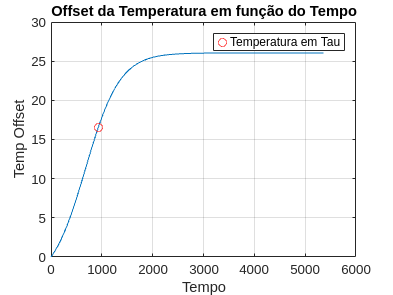



plot(time, temp_offset);
hold on;
temp_offset_at_tau = temp_offset(idx);
plot(tau, temp_offset_at_tau, 'ro'); % Destacar o ponto
title('Offset da Temperatura em função do Tempo');
legend('', 'Temperatura em Tau');
xlabel('Tempo');
ylabel('Temp Offset');
grid on;
hold off;

Achando a função de transferencia

s = tf('s');

% Kcc = Resistencia Termica
% Tau = Resistencia Termica * Capacitancia Termica
G = Kc / (tau*s + 1)


G =
 
    1733
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties


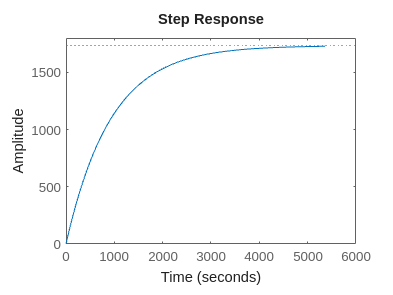

step(G, time);

Aplicando o Ganho da Potencia Elétrica pelo relé e Ganho Kph

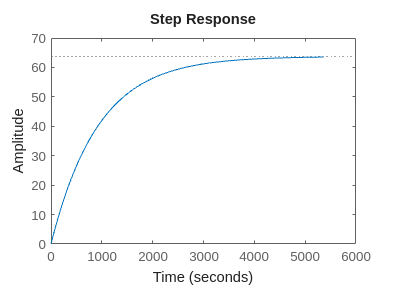

Kcc = 127^2/6.5; % chechar no atigo ganho do rele
Kr = 1/16.129;
Kph = 2.39 * 10^(-4);
K = Kcc * Kr * Kph;
step(K * G, time);


figure;
plot(time, temp_offset, 'b', 'LineWidth', 1.5); % Plota o sinal contínuo
hold on;
Kpe = 32^2 / 16.129;
step(Kpe * Kph * G, time);
hold off;

xlabel('Tempo (s)');
ylabel('Amplitude');
title('Step Response');
legend('Temperatura Experimental - Ajuste Boltzmann', 'Resposta a Função de Transferência');
grid on;

Malha fechada da função de transferencia 

H = feedback(K * G, 1)


H =
 
      63.73
  -------------
  930 s + 64.73
 
Continuous-time transfer function.
Model Properties


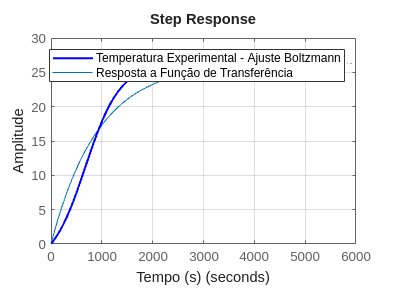

xlabel('Tempo (s)');
ylabel('Amplitude');

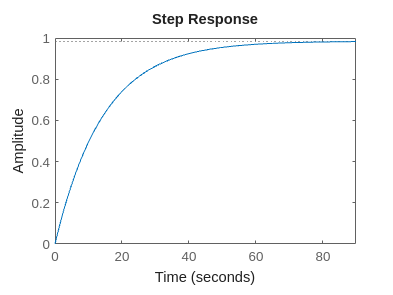

step(H);

Aplicando o controlador

O tempo de assentamento (TsT_s) pode ser aproximado por:Ts≈4ζωnT_s \approx \frac{4}{\zeta \omega_n}

Onde:

- ζ\zeta é o fator de amortecimento.

- ωn\omega_n é a frequência natural do sistema.

A função de transferência em malha fechada dada é:Gmf(s)=63.73930s+64.73G_{mf}(s) = \frac{63.73}{930s + 64.73}

Comparando com um sistema de primeira ordem padrão:

G(s)=Kτs+1G(s) = \frac{K}{\tau s + 1}

Vemos que a constante de tempo τ=930/64.73≈14.37\tau = 930 / 64.73 \approx 14.37, e o tempo de assentamento é:

Ts≈4τ=4×14.37=57.48 segundosT_s \approx 4 \tau = 4 \times 14.37 = 57.48 \text{ segundos}**Meta:**

Queremos reduzir o tempo de assentamento em **50%**, ou seja:

Tsnovo=57.482=28.74 segundosT_s^{novo} = \frac{57.48}{2} = 28.74 \text{ segundos}

Isso significa que a nova constante de tempo desejada será:

τnovo=Tsnovo4=28.744=7.19\tau_{novo} = \frac{T_s^{novo}}{4} = \frac{28.74}{4} = 7.19

Para atingir esse objetivo, aplicamos um **controlador PD**, cuja função de transferência é:

C(s)=Kp(1+Tds)C(s) = K_p (1 + T_d s)

Esse controlador afeta a constante de tempo equivalente do sistema ao aumentar o ganho efetivo do polo dominante, reduzindo a constante de tempo do sistema.

**Projeto do Controlador PD:**

A nova equação em malha fechada com o controlador PD terá a forma:

KpG(s)(1+Tds)1+KpG(s)(1+Tds)\frac{K_p G(s) (1 + T_d s)}{1 + K_p G(s) (1 + T_d s)}

Para atingir τnovo=7.19\tau_{novo} = 7.19, precisamos garantir que o novo polo do sistema seja:

τnovo=93064.73Kp=7.19\tau_{novo} = \frac{930}{64.73 K_p} = 7.19

Resolvendo para KpK_p:

Kp=9307.19×64.73≈2.06K_p = \frac{930}{7.19 \times 64.73} \approx 2.06

Agora, para o termo derivativo TdT_d, ele deve melhorar a resposta transitória sem comprometer a estabilidade. Um valor inicial razoável pode ser:

Td=1Nova frequeˆncia de cruzamentoT_d = \frac{1}{\text{Nova frequência de cruzamento}}

Como uma aproximação inicial, podemos definir Td≈1/10T_d \approx 1/10 da constante de tempo:

Td≈0.1τnovo=0.1×7.19=0.72T_d \approx 0.1 \tau_{novo} = 0.1 \times 7.19 = 0.72**Controlador PD final:**C(s)=2.06(1+0.72s)C(s) = 2.06 (1 + 0.72s)

Esse controlador deve reduzir o tempo de assentamento em 50%, acelerando a resposta do sistema. Se precisar de ajustes finos, pode-se refinar os valores de KpK_p e TdT_d por meio de simulações. 🚀

C=2.06*(1+0.72*s)


C =
 
  1.483 s + 2.06
 
Continuous-time transfer function.
Model Properties


sistema_controlado = feedback(K * G * C, 1)


sistema_controlado =
 
  94.53 s + 131.3
  ---------------
  1025 s + 132.3
 
Continuous-time transfer function.
Model Properties


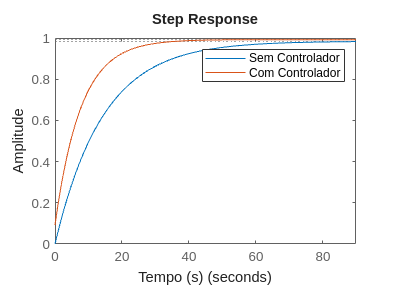


figure;
step(H);
hold on;
step(sistema_controlado);
hold off;
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Sem Controlador', 'Com Controlador');